# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\Luke\Simon\RawData_All'];              % Raw Data Folder Directory
Deci.SubjectList        = 'gui';                                                % Cell Array of strings, 'all' or 'gui'
Deci.Step               = 5 ;                                            % Which Step to implement 1-TD, 2-PP, 3-Art, 4-Analysis, 5-Plot
Deci.Proceed            = false;                                                                  % Continue to next step when current step is done?
Deci.PCom               = false;                                                      % Activates Parallel Computing for PP and Analysis only
Deci.GCom               = false; 
Deci.Folder.Version     = ['C:\Users\User\Desktop\Luke\Simon\ProcessedData'];        % Output Folder Directory

## 1. Trial Definitions 

Deci.DT.Type = 'Simon_Polymerase';
Deci.DT.Starts     = {17};                                                                      % Cell Array of Markers for Start codes.
Deci.DT.Ends       = {18};                                                                      % Cell Array of Markers for End codes.
Deci.DT.Markers    = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34] [23 24]};                                   % Cell Array of Markers for Trial Defs
Deci.DT.Locks      = [12 30 22];                                                                % Num Array for each timelock (usually Stim, Rsp and Fdb Onset )
Deci.DT.Toi        = [-2 3];                                                                    % Time of Interest, be sure to include larger window for freq                                                               % Time of Interest, be sure to include larger window for freq

Deci.DT.Displace.AddLocks = true; 
Deci.DT.Displace.Markers = {[14 15] [16 45 46 19] [300 400] [37 38] [31 34]};
Deci.DT.Displace.Duration = 1;
Deci.DT.Displace.Num = -1;

Deci.DT.Block.Markers   = {40};
Deci.DT.Block.Bisect = true;

## 2. PreProcessing Steps

Deci.PP.filter.bpfreq = [.5 80];
Deci.PP.filter.bpfilter = 'yes';
Deci.PP.filter.detrend = 'yes';

Deci.ICA.bpfreq = [1 30];
Deci.ICA.Automatic = false;

## 3. Artifact Rejection

Deci.Art.do = true;
Deci.Art.crittoilim = [-.5 1.5];
Deci.Art.RT.minlength = 200;
Deci.Art.RT.locks = [2 1];

Deci.Art.AddComponents =  false;

## 4. Analysis

if Deci.Step > 3
    Deci.DT.Markers    = {[14 15] [300 400] [31 34] [1014 1015] [1300 1400] [1031 1034]};                    
end

%Locktypes = {'Simon_Cor'}
%LockTypes = {'Simon_Cor' 'Simon_Con' 'Simon_Side' 'Simon_Contra'};
%LockTypes = {'Simon_ConCor' 'Simon_ContraCor'};
%LockTypes = {'Simon_ContraCor'};
%Locktypes = {'Simon_Congruence' 'Simon_Laterality'};
%Locktypes = {'Simon_Cor' 'Simon_Congruence' 'Simon_ConCor'};
%Locktypes = {'SimonConn_Cor'};
%Locktypes = {'Simon_Congruence'}
%LockTypes = {'Simon_Conflict'}
%Locktypes = {'Simon_CongruenceDuplets' 
%Locktypes = {'Simon_CorrectnessDuplets'}
%Locktypes = {'Simon_CongruencexCorrectnessDuplets'}
%Locktypes = {'Simon_CorrectCongruenceDuplets'}
Locktypes = {'Simon_ConCor'}

Locktypes = 1×1 cell array
    {'Simon_ConCor'}


## 5. Plotting

## ** 6. Run**

Running Deci for 25 subjects
 


Sub = struct with fields:
    Acc: {'SubjAvg'}


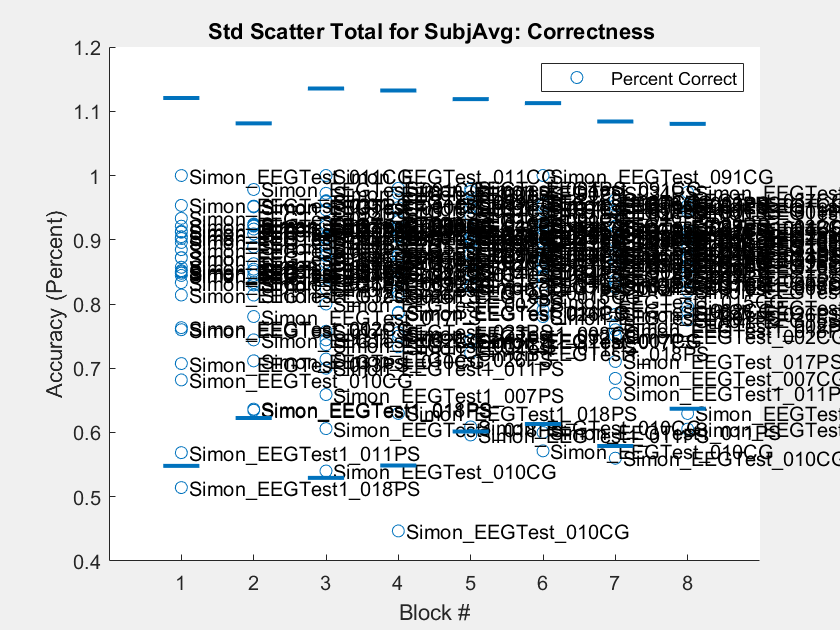

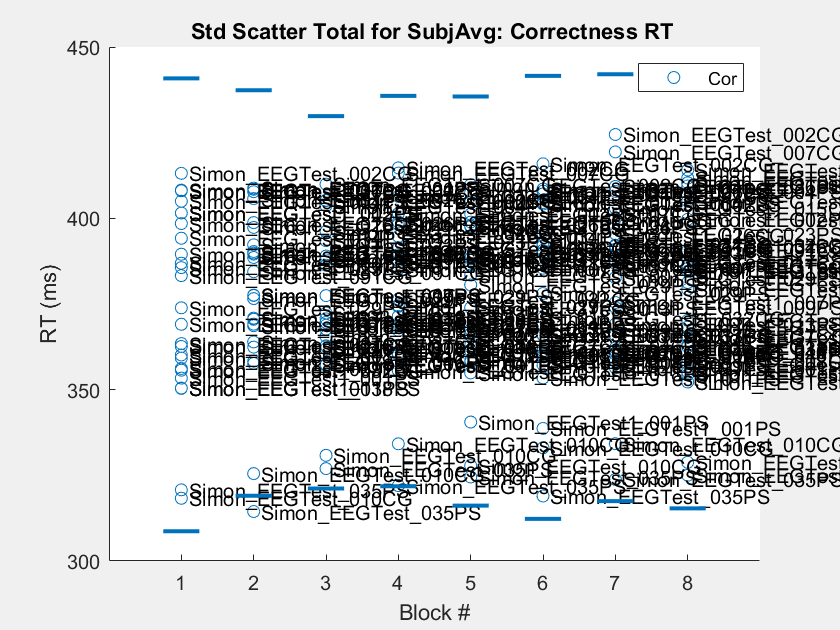

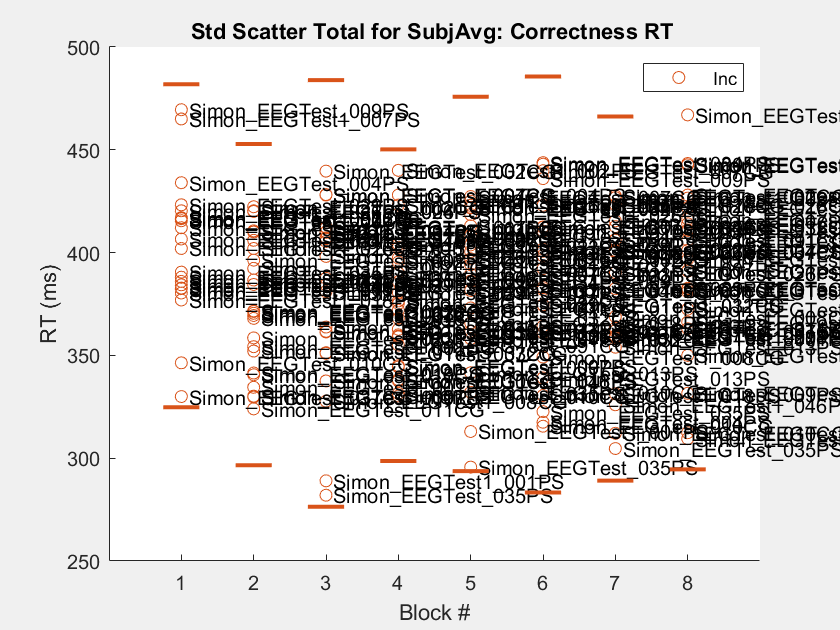

if Deci.Step == 4
    for AnalysisLocks = Locktypes
        Deci_Wavelet;
        
        Deci.Analysis.Freq.foi           = 3:1:60;                           % Frequency of Interest
        
        
        Deci.Analysis.Freq.width         = exp(linspace(log(3),log(13),40));                                                         % Width
        Deci.Analysis.Freq.Toi           = [-.5 1.5];  
        
        eval(AnalysisLocks{1})
        Deci.SubjectList        = 'gui';
       
        Deci.Analysis.Freq.do  = true;
        Deci.Analysis.ERP.do  = false;
        Deci_Backend(Deci);D
        
    end
else
    
    Simon_Cor;
    
    Deci.Run.Behavior = false;
    Deci.Run.Freq =false;
    Deci.Run.ERP =false;
    Deci.Run.CFC = false;
    Deci.Run.Extra = true;
    
    
    Deci.Plot.BslRef = 'Stim Onset';
    Deci.Plot.Lock =   'Stim Onset';
    
    Deci.Plot.GrandAverage = false;
    Deci.Plot.FreqYScale = 'linear';
    %Deci.Plot.ColorMap = flip(CoolMap);
    Deci.Plot.ImageType = 'straight';
    
    
    Deci.Plot.Topo.do    =false;
    Deci.Plot.Topo.Foi     = [4 7.5];                   % Frequency of Interest
    Deci.Plot.Topo.Toi     = [-.2 0];                   % Time of Interest
    Deci.Plot.Topo.Channel = ['Reinhart-All'];                   % Channel of Interest
    
    Deci.Plot.Square.do  =true;
    Deci.Plot.Square.Foi     = [1 inf];                 % Frequency of Interest
    Deci.Plot.Square.Toi     = [-.5 1.5];                   % Time of Interest
    Deci.Plot.Square.Channel = ['Reinhart-All'];                % Channel of Interest
    
    Deci.Plot.Wire.do    =false;
    Deci.Plot.Wire.Foi     =   [3 inf];          % Frequency of Interest
    Deci.Plot.Wire.Toi     = [];                   % Time of Interest
    Deci.Plot.Wire.Channel = ['Reinhart-All'];              % Channel of Interest
    
    Deci.Plot.Bar.do    =false;
    Deci.Plot.Bar.Foi     = [3 inf];                 % Frequency of Interest
    Deci.Plot.Bar.Toi     = [.4 .6];                   % Time of Interest
    Deci.Plot.Bar.Channel =  ['Reinhart-All'];            % Channel of Interest
    
    Deci.Plot.Freq.Type    = 'TotalPower';
    
    if  strcmpi(Deci.Plot.BslRef, 'Rsp Onset')
        Deci.Plot.Bsl     = [-.25 -.05];
    else
        Deci.Plot.Bsl     = [-.2 0];
    end
    
    Deci.Plot.BslType = 'db';
    
    %Luke(1/17/20) changed RSP reference to [-.25 -.05] & else [-.2 0] 
    
    
    if  Deci.Plot.Square.do
        Omnibus = true;
        
        
        if Omnibus == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Comp = 'Bsl';
            Deci.Plot.Stat.alpha = .01;
            Deci.Plot.Stat.correctm = 'fdr';
            %Deci.Plot.BslType = 'db';
            Deci.Plot.Stat.FPlots =  false;
        else
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.correctm = 'fdr';
        end
        Deci.Plot.Stat.FPlots =  false;
    end
    
    if Deci.Plot.Topo.do 
        Perma = true;
        
        if Perma == true
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Randomize Permutation';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
        end
    end
    
    if Deci.Plot.Wire.do
            Deci.Plot.Stat.do = true;
            Deci.Plot.Stat.Type = 'Anova/T-test';
            Deci.Plot.Stat.alpha = .05;
            Deci.Plot.Stat.FPlots =  false;
    end
        
    
    if Deci.Plot.Bar.do
        Deci.Plot.Stat.do = false;
    end
    
     if Deci.Plot.Wire.do
        Deci.Plot.Stat.do = false;
    end
    
    Deci_Backend(Deci);
end